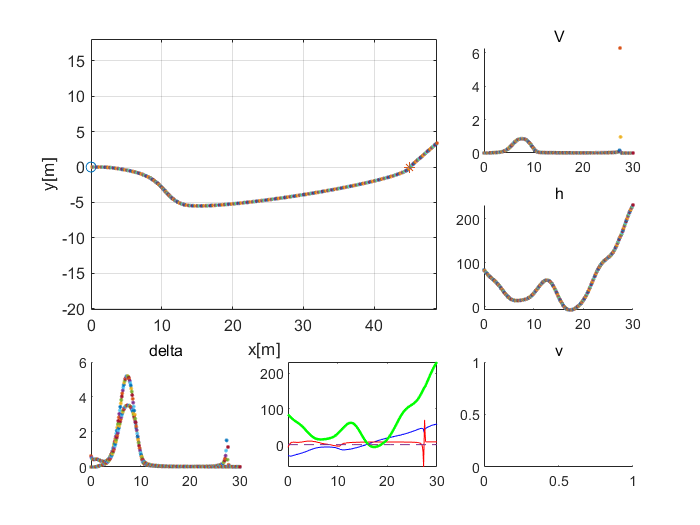

clc,clear

T=30;   %仿真时间[s]
dt=0.1;  %仿真步长

%参数
lambda=4;     %clf1比例系数
gamma=5;        %clf2比例系数
p=[0.5;2];
Br=4;          %障碍半径
x=[0;0;1.5;0];   %初始值
u_ref=[0,0];        %期望输入
H=diag([1 1 2 1]);
%坐标图

subplot(3,3,[1 2 4 5])
plot(0,0,'o'),hold on
plot(45,0,'*')
xlabel('x[m]')
ylabel('y[m]')
grid on,axis equal,hold off

subplot(3,3,3),title('V')
subplot(3,3,6),title('h')
subplot(3,3,7),title('delta')
subplot(3,3,8),title('u')
subplot(3,3,9),title('v')

%%存储矩阵
xy=zeros(2,T/dt+1);
br=zeros(2,T/dt+1);
h_log=zeros(1,T/dt+1);
dh=zeros(1,T/dt+1);
d2h=zeros(1,T/dt+1);

for t=0:dt:T
    Barrier=[10+0.8*t;3*sin(0.6*t);Br];
    [f,g]=cal_system(x);
    [h,Lfh,Lf2h,LgLfh] = cal_cbf(x,Barrier);
    [V1,V2,LfV1,LgV1,LfV2,LgV2] = cal_clf(x);
    [u,delta]=QP_solve(x,lambda,gamma,p,Barrier,u_ref,[-20 20;-20 20],H);      
    x=(f+g*u).*dt+x;
    
    xy(:,int16(t/dt+1))=x(1:2);
    br(:,int16(t/dt+1))=Barrier(1:2);
    
    %画图
    subplot(3,3,[1 2 4 5]),hold on
    plot(x(1),x(2),'.'),hold off
%     
%     subplot(3,3,3),hold on
%     plot(t,V1,'.'),hold off
%     
%     subplot(3,3,6),hold on
%     plot(t,h,'.'),hold off
%     subplot(3,3,7),hold on
%     plot(t,delta,'.'),hold off
    subplot(3,3,3),hold on
    plot(t,V1,'.'),hold off
    subplot(3,3,6),hold on
    plot(t,h,'.'),hold off
    subplot(3,3,7),hold on
    plot(t,delta,'.'),hold off
    subplot(3,3,8),hold on
    plot(t,u,'.'),hold off
%     subplot(3,3,9),hold on
%     plot(t,x(3),'.'),hold off
%     if h<0
%         %Lf2h+(p(1)+p(2))*Lfh+p(1)*p(2)*h+LgLfh*u
%         Lfh;
%         break
%     end
    h_log(int32(t/dt+1))=h;
    dh(int32(t/dt+1))=Lfh;
    d2h(int32(t/dt+1))=Lf2h+LgLfh*u;
end
plot(0:dt:T,dh,'b')
hold on
plot(0:dt:T,d2h,'r')
plot(0:dt:T,h_log,'g','LineWidth',1.5)
plot(0:dt:T,zeros(T/dt+1,1),'--')

%daws